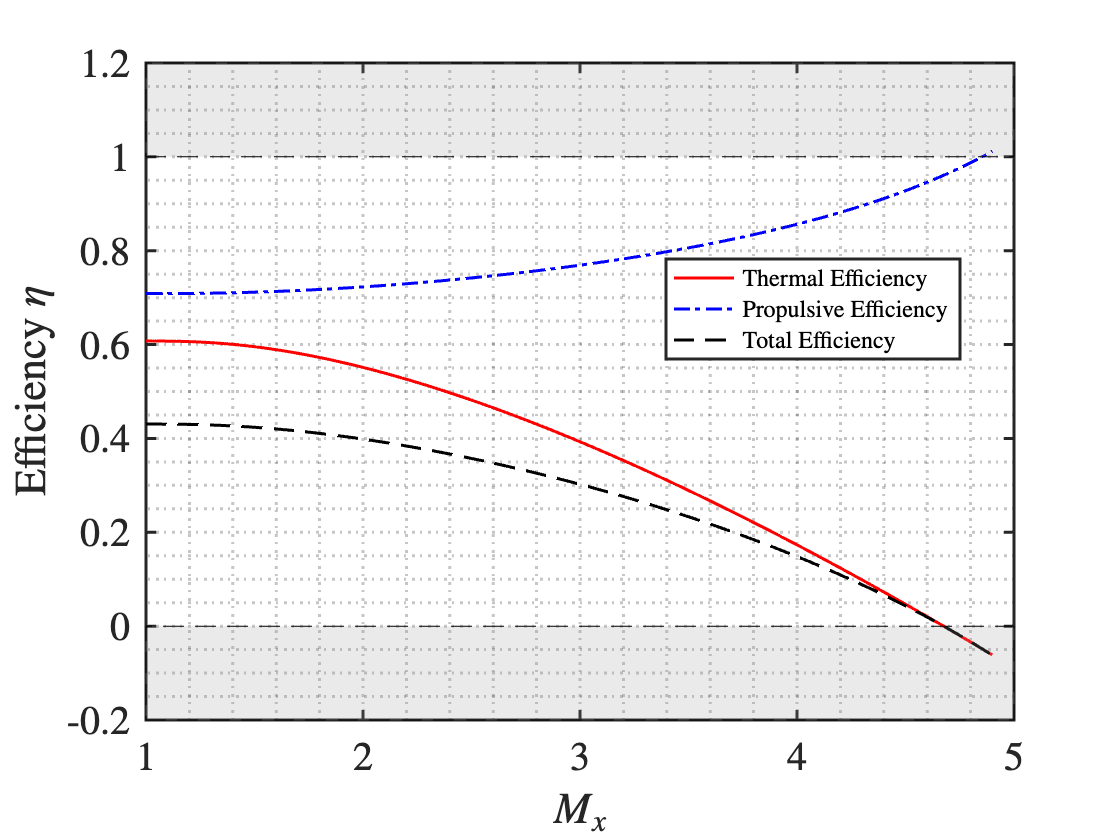

% Advanced Propulsion CW, plot 4-6 varying:
% 1. Normal Shock Strength
% 2. Burner Entry Mach Number
% 3. Burner Temperature


%------Normal Shock Strength--------

clear; clc; close all 

P_1 = 7e4;                           %ambient pressure
T_1 = 210;                           %ambient temperature
M_1 = 2.8;                           %free stream mach number
M_x = [1:0.01:4.9];                     %normal shock strength (before shock mach number)
M_2 = 0.2;                           %burner entry mach number
T_b = 1700;                          %maximum burner temperature
Pb_P2 = 1;                           %burner pressure ratio
P4_P1 = 1;                           %exhaust pressure ratio
F = 5e5;                             %required thrust

for i = 1:length(M_x)
    %[A1(i), At1(i), Abe(i), Abx(i), At3(i), Ae(i), thermeff(i), propeff(i)] = ramjet(pa,Ta,Mf,Shock(i),Mbe,Tb,bpr,epr,thrust);
    [M_4(i), M_b(i), T_2(i), T_4(i), A_1(i), A_C1(i), A_2(i), A_b(i), A_C2(i), A_4(i), eta_th(i), eta_p(i)] = RamjetDesign1(P_1, T_1, M_1, M_x(i), M_2, T_b, Pb_P2, P4_P1, F);
end


% Plots for M_x - efficiencies plot
figure
plot(M_x, eta_th, 'LineWidth',1.5, 'Color', 'r')
hold on  
plot(M_x, eta_p,'LineWidth',1.5, 'Color', 'b','LineStyle','-.')
plot(M_x, eta_th.*eta_p,'LineWidth',1.5, 'Color', 'k','LineStyle','--')
II=patch([[1 5] fliplr([1 5])],[[1 1] fliplr([1.2 1.2])], [.58, .58, .58],'linestyle','--');
alpha(0.2);
II=patch([[1 5] fliplr([1 5])],[[-0.2 -0.2] fliplr([0 0])], [.58, .58, .58],'linestyle','--');
alpha(0.2);


grid minor 
xlabel("$M_x$", Interpreter="latex")
ylabel("Efficiency $\eta$", Interpreter="latex")
legend('Thermal Efficiency', 'Propulsive Efficiency', 'Total Efficiency','interpreter', 'latex', FontSize=12)
hold off
box on

ax = gca;
ax.FontSize = 20;  
set(gca,'TickLabelInterpreter','latex')
set(gca,'linewidth',1.5)
legend("Position",[0.59461,0.57302,0.2625,0.11905])

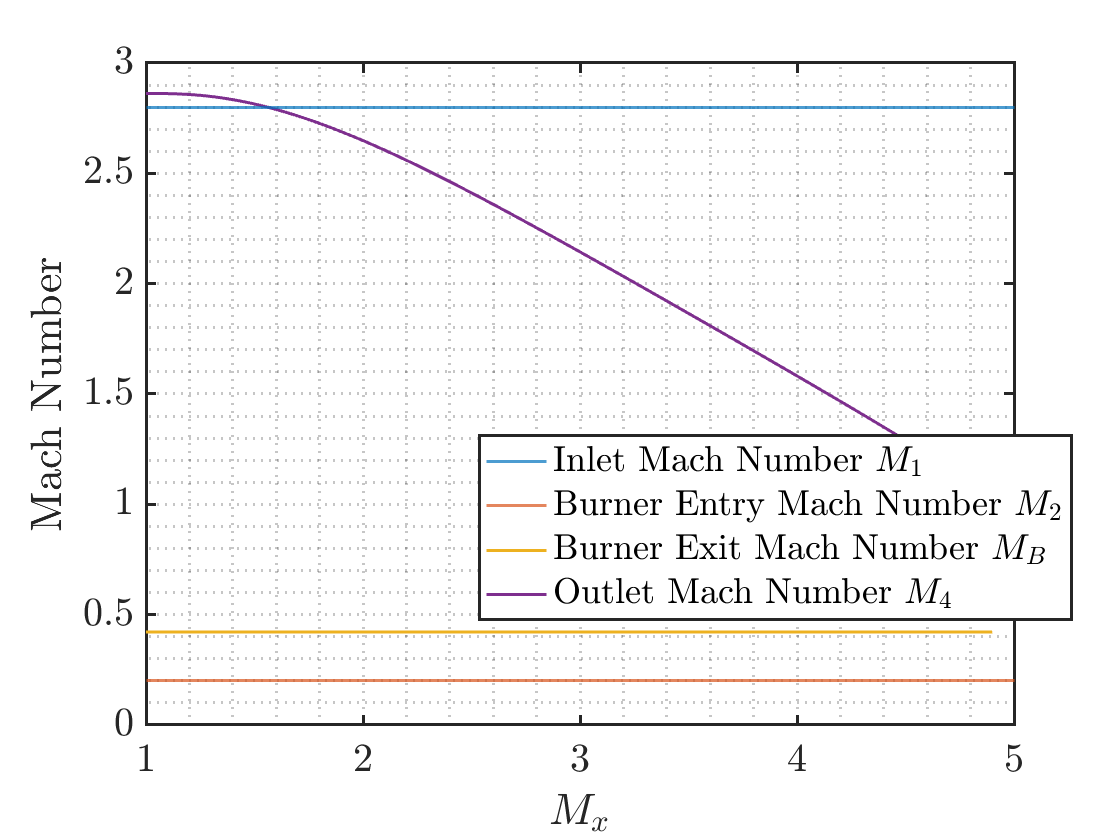



% Plots for M_x - Mach Number plots
figure;
yline(M_1,'LineWidth',1.5,'color',[0 0.4470 0.7410])
hold on
yline(M_2, 'LineWidth',1.5,'color',[0.8500 0.3250 0.0980])
plot(M_x, M_b, 'LineWidth',1.5 ,'color',[0.9290 0.6940 0.1250])
plot(M_x, M_4, 'LineWidth',1.5,'color',[0.4940 0.1840 0.5560])
hold off
box on
grid minor

xlabel("$M_{x}$", Interpreter="latex")
ylabel("Mach Number", Interpreter="latex")
legend('Inlet Mach Number $M_1$', 'Burner Entry Mach Number $M_2$', 'Burner Exit Mach Number $M_B$', 'Outlet Mach Number $M_4$', Interpreter="latex")

ax = gca;
ax.FontSize = 20; 
set(gca,'TickLabelInterpreter','latex')
set(gca,'linewidth',1.5)
legend("Position",[0.48435,0.28765,0.41522,0.16738])

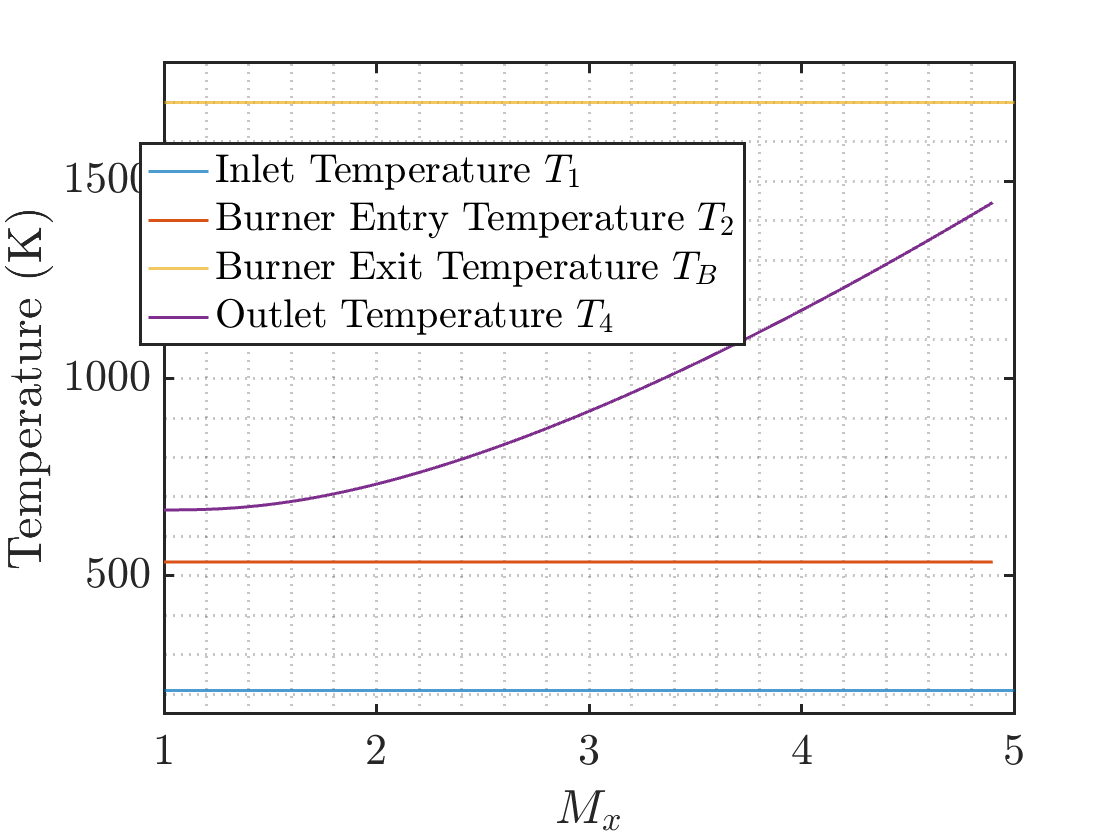




% Plots for M_x - Temperature plots
figure;
yline(T_1,'LineWidth',1.5,'color',[0 0.4470 0.7410])
hold on
plot(M_x,T_2, 'LineWidth',1.5,'color',[0.8500 0.3250 0.0980])
yline(T_b, 'LineWidth',1.5,'color',[0.9290 0.6940 0.1250])
plot(M_x, T_4, 'LineWidth',1.5,'color',[0.4940 0.1840 0.5560])
hold off
grid minor
box on

ylim([150,1800])
xlabel("$M_{x}$", Interpreter="latex")
ylabel("Temperature (K)", Interpreter="latex")
legend('Inlet Temperature $T_1$', 'Burner Entry Temperature $T_2$', 'Burner Exit Temperature $T_B$', 'Outlet Temperature $T_4$', Interpreter="latex")

ax = gca;
ax.FontSize = 22;  
set(gca,'TickLabelInterpreter','latex')
set(gca,'linewidth',1.5)
legend("Position",[0.19962,0.6254,0.39058,0.16738])

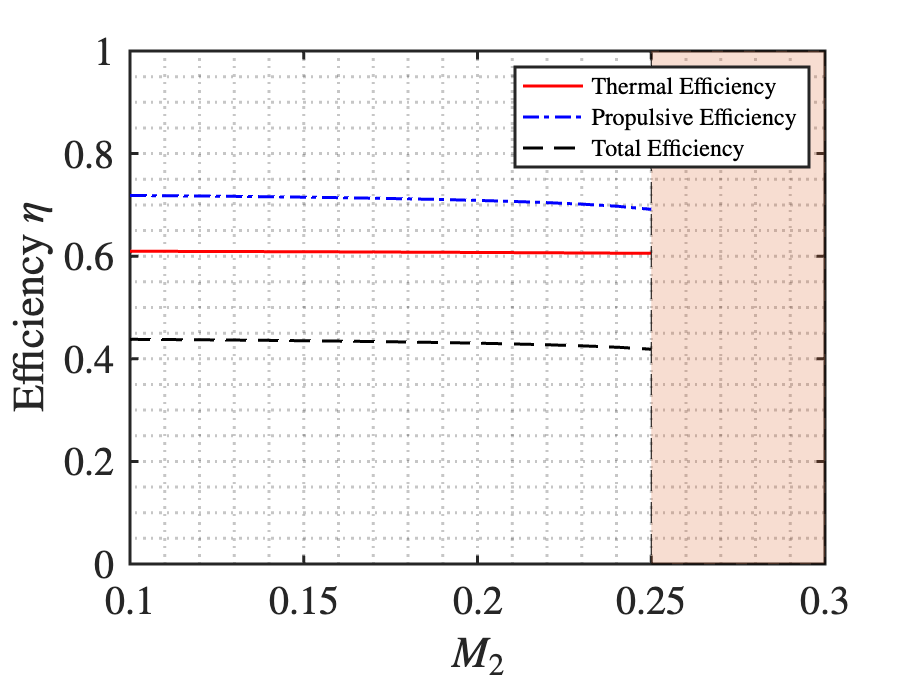



clear; clc; close all 
%------Burner Entry Mach Number-------

P_1 = 7e4;                           %ambient pressure
T_1 = 210;                           %ambient temperature
M_1 = 2.8;                           %free stream mach number
M_x = 1.1;                           %normal shock strength (before shock mach number)
M_2 = [0.1:0.01:0.25];               %burner entry mach number
T_b = 1700;                          %maximum burner temperature
Pb_P2 = 1;                           %burner pressure ratio
P4_P1 = 1;                           %exhaust pressure ratio
F = 5e5;                             %required thrust

for i = 1:length(M_2)
    %[A1(i), At1(i), Abe(i), Abx(i), At3(i), Ae(i), thermeff(i), propeff(i)] = ramjet(pa,Ta,Mf,Shock(i),Mbe,Tb,bpr,epr,thrust);
    [M_4(i), M_b(i), T_2(i),T_4(i), A_1(i), A_C1(i), A_2(i), A_b(i), A_C2(i), A_4(i), eta_th(i), eta_p(i)] = RamjetDesign1(P_1, T_1, M_1, M_x, M_2(i), T_b, Pb_P2, P4_P1, F);
end


figure
plot(M_2, eta_th, 'LineWidth',1.5, 'Color', 'r')
hold on  
plot(M_2, eta_p,'LineWidth',1.5, 'Color', 'b','LineStyle','-.')
plot(M_2, eta_th.*eta_p,'LineWidth',1.5, 'Color', 'k','LineStyle','--')
grid minor 
xlabel("$M_{2}$", Interpreter="latex")
ylabel("Efficiency $\eta$", Interpreter="latex")
xlim([0.1 0.3])
ylim([0 1])

II=patch([[0.25 0.3] fliplr([0.25 0.3])],[[0 0] fliplr([1 1])], [0.8500 0.3250 0.0980],'linestyle','--');
alpha(0.2);
ax = gca;
ax.FontSize = 20;  
set(gca,'TickLabelInterpreter','latex')
set(gca,'linewidth',1.5)
legend('Thermal Efficiency', 'Propulsive Efficiency', 'Total Efficiency','interpreter', 'latex', FontSize=12)

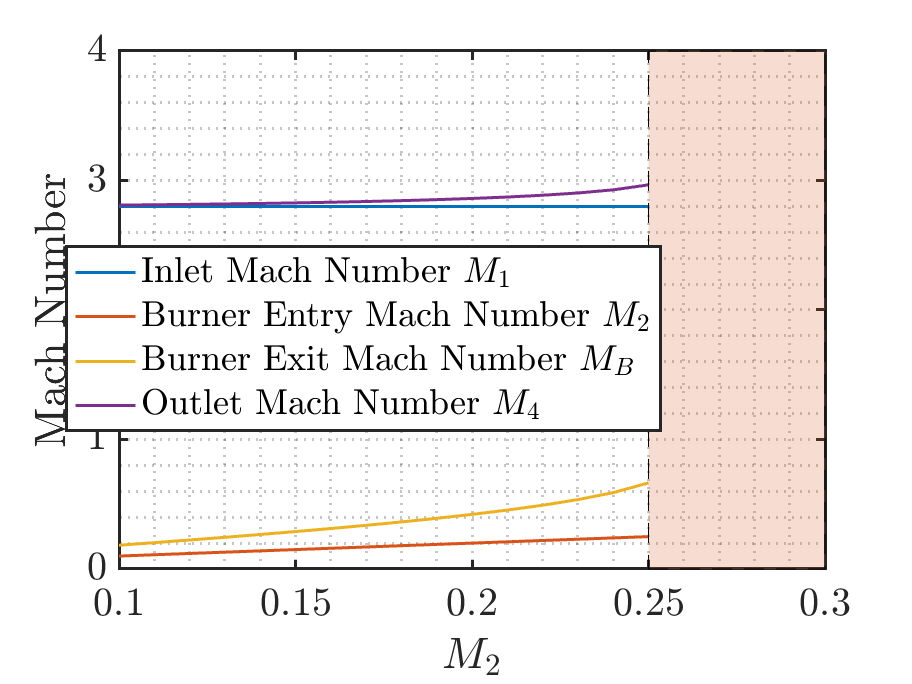




% Plots for M_2 - Mach Number plots
figure
line([0.1, 0.25], [M_1,M_1],'LineWidth',1.5,'color',[0 0.4470 0.7410])
hold on
plot(M_2, M_2, 'LineWidth',1.5,'color',[0.8500 0.3250 0.0980])
plot(M_2, M_b, 'LineWidth',1.5,'color',[0.9290 0.6940 0.1250])
plot(M_2, M_4, 'LineWidth',1.5,'color',[0.4940 0.1840 0.5560])
hold off
grid minor
box on

xlim([0.1 0.3])
ylim([0 4])
xlabel("$M_{2}$", Interpreter="latex")
ylabel("Mach Number", Interpreter="latex")
II=patch([[0.25 0.3] fliplr([0.25 0.3])],[[0 0] fliplr([4 4])], [0.8500 0.3250 0.0980],'linestyle','--');
alpha(0.2);

legend('Inlet Mach Number $M_1$', 'Burner Entry Mach Number $M_2$', 'Burner Exit Mach Number $M_B$', 'Outlet Mach Number $M_4$', Interpreter="latex")
ax = gca;
ax.FontSize = 20; 
set(gca,'TickLabelInterpreter','latex')
set(gca,'linewidth',1.5)
legend("Position",[0.19095,0.42098,0.41522,0.16738])

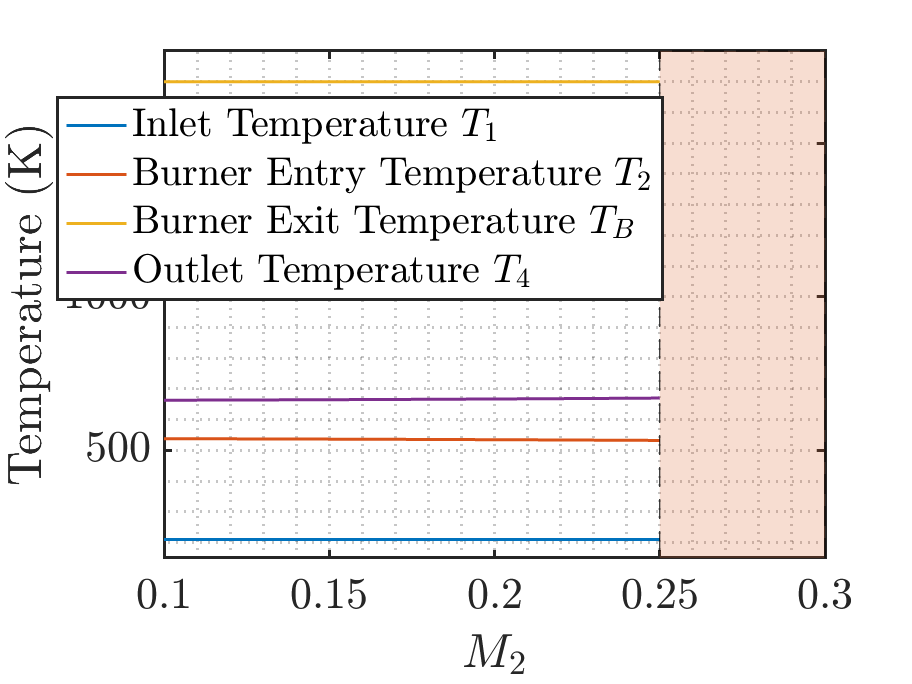



% Plots for M_2 - Temperature plots
figure
line([0.1, 0.25], [T_1,T_1],'LineWidth',1.5,'color',[0 0.4470 0.7410])
hold on
plot(M_2, T_2, 'LineWidth',1.5,'color',[0.8500 0.3250 0.0980])
line([0.1, 0.25], [T_b,T_b], 'LineWidth',1.5,'color',[0.9290 0.6940 0.1250])
plot(M_2, T_4, 'LineWidth',1.5,'color', [0.4940 0.1840 0.5560])
hold off
grid minor
box on

xlim([0.1 0.3])
ylim([150,1800])
xlabel("$M_{2}$", Interpreter="latex")
ylabel("Temperature (K)", Interpreter="latex")

II=patch([[0.25 0.3] fliplr([0.25 0.3])],[[0 0] fliplr([1800 1800])], [0.8500 0.3250 0.0980],'linestyle','--');
alpha(0.2);
legend('Inlet Temperature $T_1$', 'Burner Entry Temperature $T_2$', 'Burner Exit Temperature $T_B$', 'Outlet Temperature $T_4$', Interpreter="latex")
ax = gca;
ax.FontSize = 22;  
set(gca,'TickLabelInterpreter','latex')
set(gca,'linewidth',1.5)
legend("Position",[0.19962,0.6254,0.39058,0.16738])

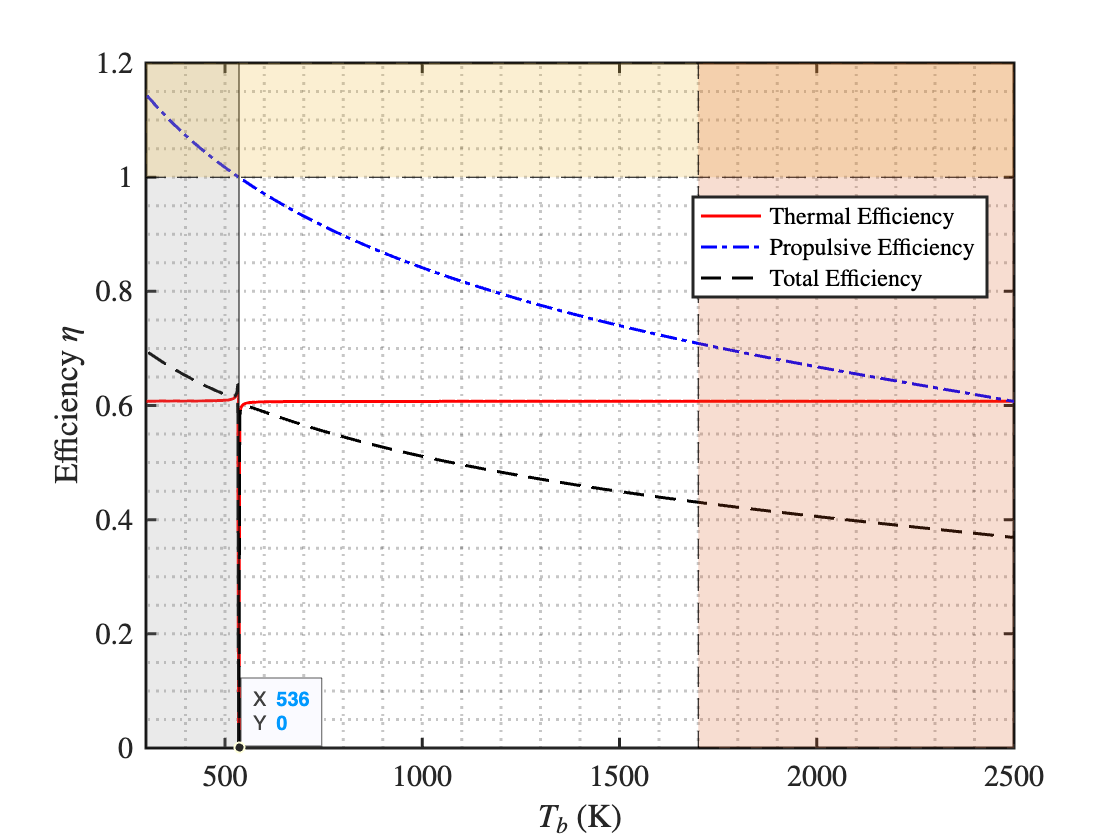


clear; clc; close all 
%-------Burner Temperature-----------

P_1 = 7e4;                           %ambient pressure
T_1 = 210;                           %ambient temperature
M_1 = 2.8;                           %free stream mach number
M_x = 1.1;                           %normal shock strength (before shock mach number)
M_2 = 0.2;                           %burner entry mach number
T_b = linspace(135,2500,1000);        %maximum burner temperature
Pb_P2 = 1;                           %burner pressure ratio
P4_P1 = 1;                           %exhaust pressure ratio
F = 5e5;                             %required thrust

for i = 1:length(T_b)
    %[A1(i), At1(i), Abe(i), Abx(i), At3(i), Ae(i), thermeff(i), propeff(i)] = ramjet(pa,Ta,Mf,Shock(i),Mbe,Tb,bpr,epr,thrust);
    [M_4(i), M_b(i), T_2(i),T_4(i), A_1(i), A_C1(i), A_2(i), A_b(i), A_C2(i), A_4(i), eta_th(i), eta_p(i)] = RamjetDesign1(P_1, T_1, M_1, M_x, M_2, T_b(i), Pb_P2, P4_P1, F);
end

figure
plot(T_b, eta_th, 'LineWidth',1.5, 'Color', 'r')
hold on  
plot(T_b, eta_p,'LineWidth',1.5, 'Color', 'b','LineStyle','-.')
plot(T_b, eta_th.*eta_p,'LineWidth',1.5, 'Color', 'k','LineStyle','--')
grid minor 
box on
xlabel("$T_b$ (K)", Interpreter="latex")
ylabel("Efficiency $\eta$", Interpreter="latex")
ylim([0 1.2])
xlim([300 2500])


II=patch([[300 536] fliplr([300 536])],[[0 0] fliplr([1.2 1.2])], [.58, .58, .58],'linestyle','-');
alpha(0.2);
II=patch([[300 2500] fliplr([300 2500])],[[1 1] fliplr([1.2 1.2])], [0.9290 0.6940 0.1250],'linestyle','--');
alpha(0.2);
II=patch([[1700 2500] fliplr([1700 2500])],[[0 0] fliplr([1.2 1.2])], [0.8500 0.3250 0.0980],'linestyle','--');
alpha(0.2);
legend('Thermal Efficiency', 'Propulsive Efficiency', 'Total Efficiency','interpreter', 'latex', FontSize=12)
ax = gca;
ax.FontSize = 15;  % Font Size of 15
set(gca,'TickLabelInterpreter','latex')
set(gca,'linewidth',1.5)
legend("Position",[0.6189,0.64616,0.2625,0.11905])

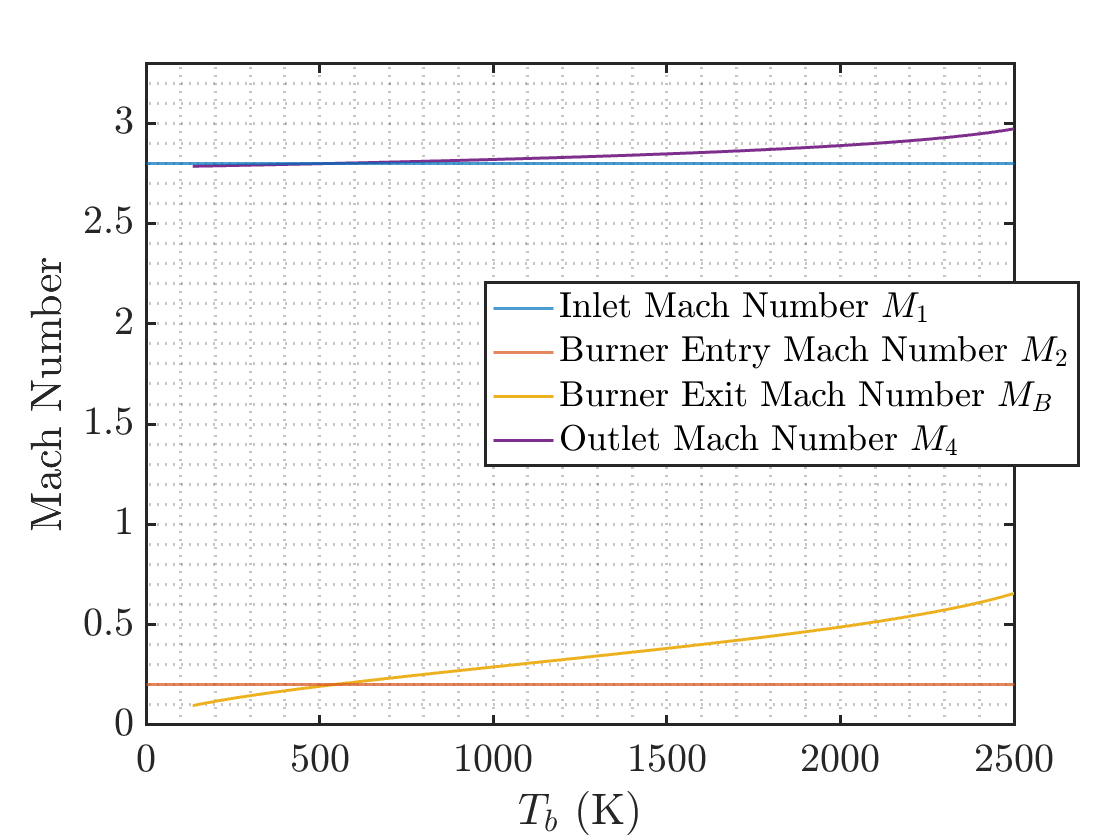




% Plots for T_b - Mach Number plots
figure
yline(M_1,'LineWidth',1.5,'color',[0 0.4470 0.7410])
hold on
yline(M_2, 'LineWidth',1.5,'color',[0.8500 0.3250 0.0980])
plot(T_b, M_b, 'LineWidth',1.5,'color',[0.9290 0.6940 0.1250])
plot(T_b, M_4, 'LineWidth',1.5,'color', [0.4940 0.1840 0.5560])
hold off
grid minor
box on

ylim([0 3.3])
xlabel("$T_b$ (K)", Interpreter="latex")
ylabel("Mach Number", Interpreter="latex")
legend('Inlet Mach Number $M_1$', 'Burner Entry Mach Number $M_2$', 'Burner Exit Mach Number $M_B$', 'Outlet Mach Number $M_4$', Interpreter="latex")

ax = gca;
ax.FontSize = 20;  % Font Size of 15
set(gca,'TickLabelInterpreter','latex')
set(gca,'linewidth',1.5)
legend("Position",[0.49007,0.47037,0.41522,0.16738])

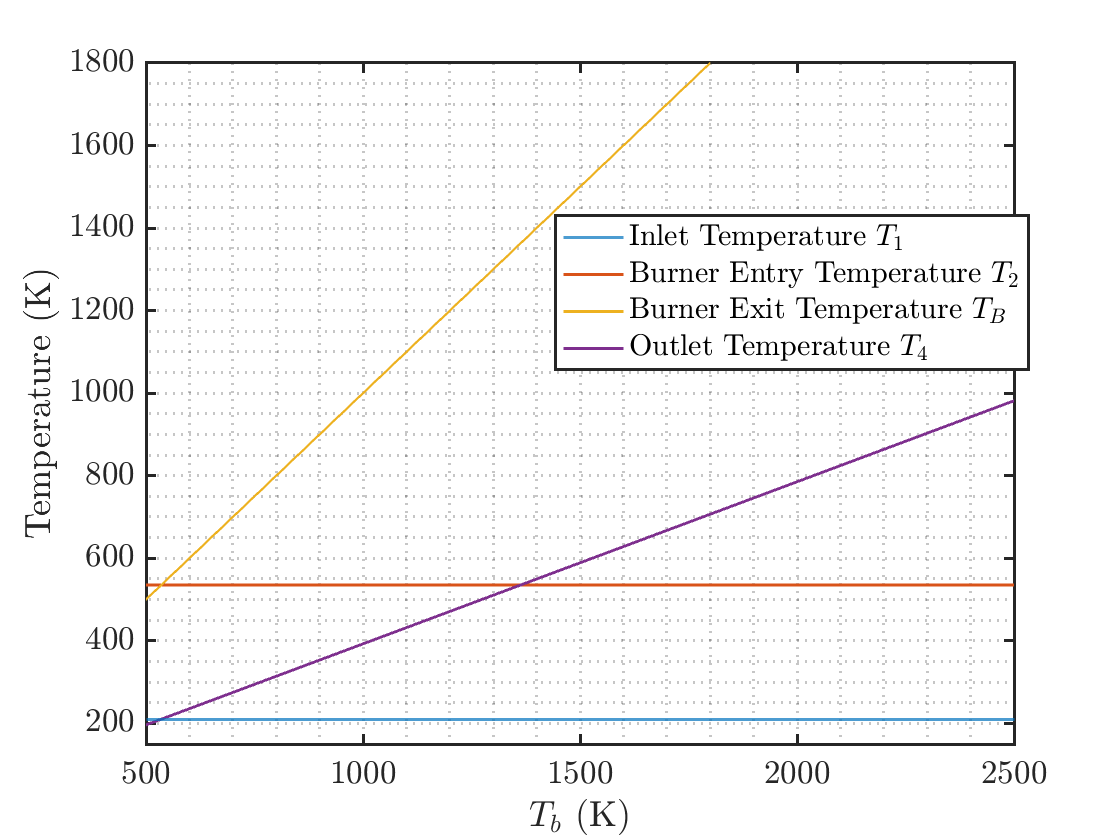




% Plots for T_b - Temperature plots
figure
yline(T_1,'LineWidth',1.5,'color',[0 0.4470 0.7410])
hold on
plot(T_b,T_2, 'LineWidth',1.5,'color',[0.8500 0.3250 0.0980])
plot(T_b, T_b, 'LineWidth',1.5,'color',[0.9290 0.6940 0.1250])
plot(T_b, T_4, 'LineWidth',1.5,'color', [0.4940 0.1840 0.5560])
hold off
grid minor
box on

ylim([150,1800])
xlim([500 2500])
xlabel("$T_b$ (K)", Interpreter="latex")
ylabel("Temperature (K)", Interpreter="latex")
legend('Inlet Temperature $T_1$', 'Burner Entry Temperature $T_2$', 'Burner Exit Temperature $T_B$', 'Outlet Temperature $T_4$', Interpreter="latex")
ax = gca;
ax.FontSize = 16.5;  % Font Size of 15
set(gca,'TickLabelInterpreter','latex')
set(gca,'linewidth',1.5)
legend("Position",[0.51171,0.56735,0.39058,0.16738])